# Read all the images 

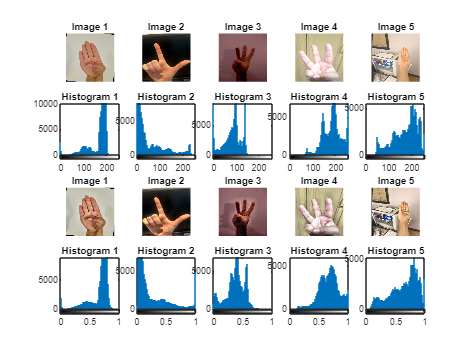

% Directory path
directory = 'Datasets\Task1\Images';
folderpath='Train';

% Get a list of all files in the directory
fileList = dir(fullfile(directory, '*.jpg'));

% Loop through the list and read each image
images = cell(1, 5); % Initialize cell array to store images
images_eq = cell(1, 5);
images_squared = cell(1, 5);
list=[1 ,2 ,9 ,29 ,38 ];

for i = 1:5
    % Get the file name
    fileName = fullfile(directory, fileList(list(i)).name);
    
    % Read the image
    image = imread(fileName);
    
    % Store the image in the cell array
    
    images{i} = image;

    LAB = rgb2lab(image);
    L = LAB(:,:,1)/100;
    L = adapthisteq(L,'NumTiles',[8 8],'ClipLimit',0.005);
    LAB(:,:,1) = L*100;
    J = lab2rgb(LAB);
    images_eq{i}=J;

end

% Display the images like a filmstrip
figure;
subplot(4,5,1);imshow(images{1});title('Image 1');
subplot(4,5,2);imshow(images{2});title('Image 2');
subplot(4,5,3);imshow(images{3});title('Image 3');
subplot(4,5,4);imshow(images{4});title('Image 4');
subplot(4,5,5);imshow(images{5});title('Image 5');
subplot(4,5,6);imhist(images{1});title('Histogram 1');
subplot(4,5,7);imhist(images{2});title('Histogram 2');
subplot(4,5,8);imhist(images{3});title('Histogram 3');
subplot(4,5,9);imhist(images{4});title('Histogram 4');
subplot(4,5,10);imhist(images{5});title('Histogram 5');
subplot(4,5,11);imshow(images_eq{1});title('Image 1');
subplot(4,5,12);imshow(images_eq{2});title('Image 2');
subplot(4,5,13);imshow(images_eq{3});title('Image 3');
subplot(4,5,14);imshow(images_eq{4});title('Image 4');
subplot(4,5,15);imshow(images_eq{5});title('Image 5');
subplot(4,5,16);imhist(images_eq{1});title('Histogram 1');
subplot(4,5,17);imhist(images_eq{2});title('Histogram 2');
subplot(4,5,18);imhist(images_eq{3});title('Histogram 3');
subplot(4,5,19);imhist(images_eq{4});title('Histogram 4');
subplot(4,5,20);imhist(images_eq{5});title('Histogram 5');

## Parse the skin colour 

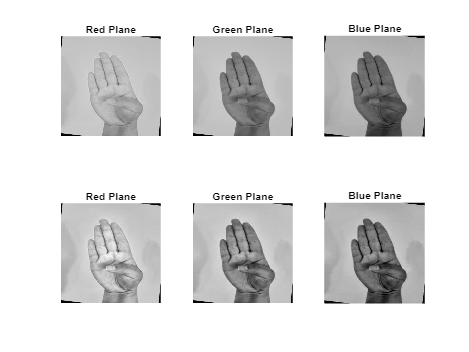

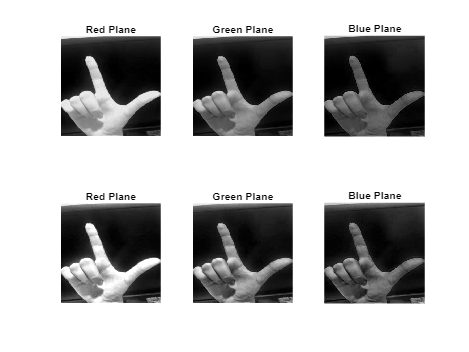

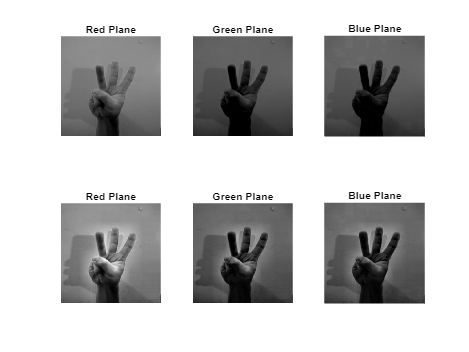

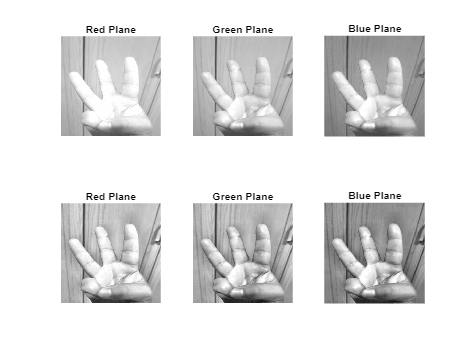

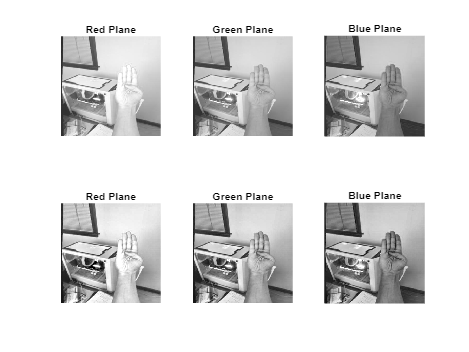

for n=1:5

    img=images{n};
    img2=images_eq{n};

    [R,G,B]=imsplit(img);
    [R2,G2,B2]=imsplit(img2);

    figure();
    subplot(2,3,1);imshow(R);title('Red Plane');
    subplot(2,3,2);imshow(G);title('Green Plane');
    subplot(2,3,3);imshow(B);title('Blue Plane');
    subplot(2,3,4);imshow(R2);title('Red Plane');
    subplot(2,3,5);imshow(G2);title('Green Plane');
    subplot(2,3,6);imshow(B2);title('Blue Plane');
end